# 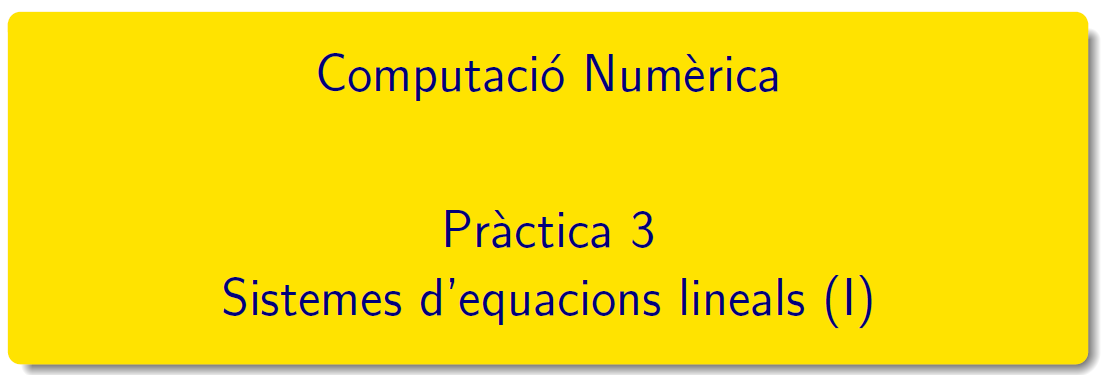

=====================================================================================

# Pràctica 3 - Segona part

## Aprenem...

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document  CN-tema2-QT2223.pdf que podeu trobar en el campus virtual. Vector residu

#### `Exercici 1``. Normes matricials`

`Fent ús de les normes `${||\cdot||}_1\,,\ {||\cdot||}_2 \  i \ {||\cdot||}_\infty$ `calculeu les normes de les matrius següents:`


$$a)\ \left (\begin{array}{cc} a+1 & a\\ a &
		a-1 \end{array}\right )$$



$$b)\ \left (\begin{array}{cc} 0 & 1\\ -2 & 0 \end{array}\right )$$


A=[0 1; -2 1];
n1 = norm(A,1), ninf=norm(A,'inf'),nF=norm(A,'fro'),n2=norm(A)

n1 = 2

ninf = 3

nF = 2.4495

n2 = 2.2882

sqrt(eig(A'*A))

ans =     0.8740
    2.2882



$$c)\ \left (\begin{array}{cc} \alpha & 1\\ 1 & 1 \end{array}\right )$$


syms alpha 
assume(alpha +1 >2)
A = [alpha,1; 1 1]

$$A = \left(\begin{array}{cc} \alpha & 1\\ 1 & 1 \end{array}\right)$$

n1 = norm(A,1), ninf=norm(A,'inf'),nF=norm(A,'fro'),n2=norm(A)

$$n1 = \max\left(\alpha +1,2\right)$$

$$ninf = \max\left(\alpha +1,2\right)$$

$$nF = \sqrt{\alpha^{2}+3}$$

$$n2 = \sqrt{\max\left(\frac{\alpha \,\sqrt{\alpha^{2}-2\,\alpha +5}}{2}+\frac{\sqrt{\alpha^{2}-2\,\alpha +5}}{2}+\frac{\alpha^{2}}{2}+\frac{3}{2},\left|\frac{\alpha^{2}}{2}-\frac{\sqrt{\alpha^{2}-2\,\alpha +5}}{2}-\frac{\alpha \,\sqrt{\alpha^{2}-2\,\alpha +5}}{2}+\frac{3}{2}\right|\right)}$$

#### `Exercici 2``. Vector residu. Error absolut.`

`Fent ús de les normes `${||\cdot||}_1\,,\ {||\cdot||}_2 \  i \ {||\cdot||}_\infty$ `calculeu `$||x-x^{*}||$ i $||Ax^{*}-b||$` en el cas següent`


$$\ (A\vert\,b)= \left (
	\begin{array}{ccrcc} 3.3330 & 15920 & -10.333 &\vert & 15913\\
		2.2220 & 16.710 & 9.6120 &\vert & 28.544\\
		1.5611 & 5.1791 & 1.6852 &\vert & 8.4254 \end{array}\right )
	\quad x= \left (\begin{array}{r} 1 \\ 1 \\ 1 \end{array}\right )
	\quad x^{*} = \left (\begin{array}{r} 1.2001\\ 0.99991\\ 0.92538
	\end{array}\right)$$


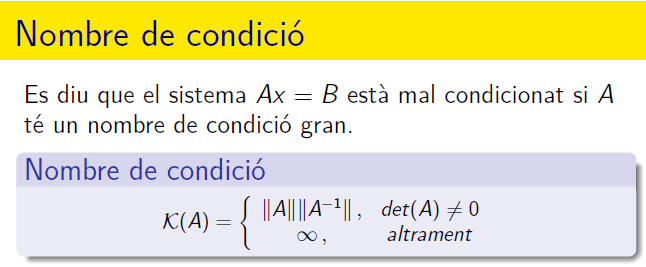

### Nombre de condició d'una matriu

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [Condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format rat
H = hilb(4)

H =        1              1/2            1/3            1/4     
       1/2            1/3            1/4            1/5     
       1/3            1/4            1/5            1/6     
       1/4            1/5            1/6            1/7     


format longG
condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

condN2 =            15513.738738929


condN1 =           28374.9999999973


condNf =           15613.7935596423


condNi =           28374.9999999973


#### `Exemple`

Obteniu el nombre de condició de la matriu següent  $\left( \begin{array}{rr}
		1 & 1+\epsilon \\
		1+\epsilon & 1
		\end{array}\right) $

% syms e
% assume(e>0)
% A=[1,1+e;1+e,1]
% n1 = norm(A,1)
% determinant = det(A)
% AI = inv(A)
% n2 = simplifyFraction(norm(AI,1))
% simplifyFraction(cond(A,'inf'))

#### `Exercici 3``. Càlcul del nombre de condició`

`Fent ús de les normes `${||\cdot||}_1\,,\ {||\cdot||}_2 \  i \ {||\cdot||}_\infty$ `calculeu els nombres de condició de les matrius següents:`


$$a)\ \left (\begin{array}{cc} a+1 & a\\ a &
		a-1 \end{array}\right )$$



$$b)\ \left (\begin{array}{cc} 0 & 1\\ -2 & 0 \end{array}\right )$$



$$c)\ \left (\begin{array}{cc} \alpha & 1\\ 1 & 1 \end{array}\right )$$


 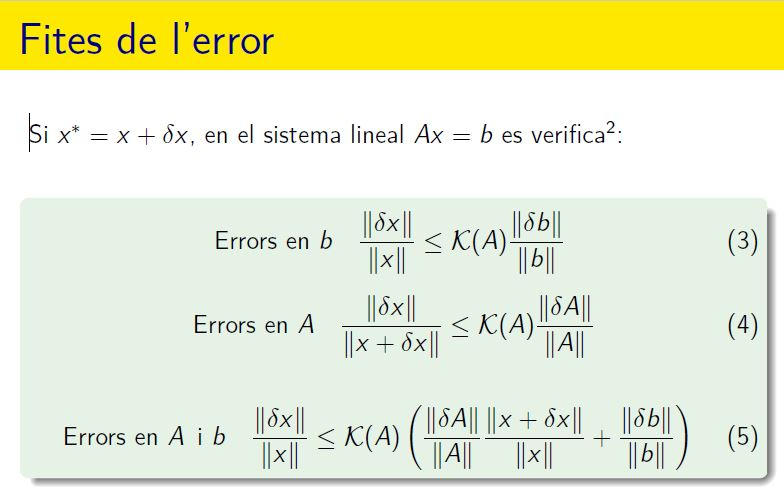     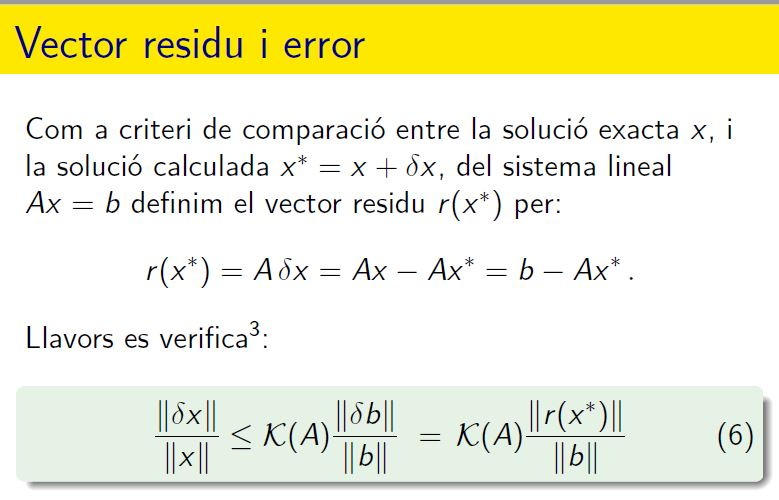

El nombre de condició d'una matriu apareix en les fites de l'error relatiu del resultat. 

Aquestes fites les podeu trobar en el llibre de la bibliografia Càlcul Numèric, Grau, M. i Noguera, M.

#### `Exercici 4.`` Propagació dels errors en les dades d'un sistema lineal`


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudiem com varia la solució del sistema lineal quan modifiquem només el terme independent $A(x+\delta x) = b+\delta b$

format shortG
A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

Sistema lineal 

% b1=[32; 23; 33; 31];
% b2=[32.1; 22.9; 33.1; 30.9];
% B=[b1,b2], x=linsolve(A,B)
% fprintf('paràmetres de condicionament\n'),K=cond(A,1), RK=rcond(A)
% fprintf('pertorbació en el vector b: db\n'), db = norm(b1-b2,'inf')/norm(b1,'inf')
% fprintf('pertorbació en el vector x: dx\n'),dx = norm(x(:,1)-x(:,2),'inf')/norm(x(:,1),'inf')
% fprintf('Error amplificat fp :\n'), fp = dx/db


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.1& 7.2 & 32\\
7.08 & 5.04 & 6 & 5 & 23\\
8 & 5.98 & 9.89 & 9 & 33\\
6.99 & 4.99 & 9 & 9.98& 31\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudieu com varia la solució del sistema lineal quan modifiquem només la matriu del sistema $(A+\Delta)(x+\delta x) = b$

% Càlculs per fer



$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.1& 7.2 & 32.1\\
7.08 & 5.04 & 6 & 5 & 22.9\\
8 & 5.98 & 9.89 & 9 & 33.1\\
6.99 & 4.99 & 9 & 9.98& 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudiem com varia la solució del sistema lineal quan  la matriu del sistema i el vector terme independent $(A+\Delta)(x+\delta x) = b+\delta b$

% Càlculs per fer



### Sistemes d'equacions lineals sobredeterminats

Un sistema **Ax=b**, on A és una matriu mxn (m>n) i de rang n es diu sistema sobredeterminat.  No existeix $x=(x_1,x_2,\cdots,x_n)^t$ solució. 

`Exemple`


$$\left\{ \begin{array}{rrrrr}
	x_1&+&x_2 & = &1\,,\\
	x_1&+&2x_2 & = & 2\,,\\
	x_1&+&3x_2 & = & 5\,.\\
	\end{array}\right.$$
      

`Escriviu A i b i calculeu rang(A), rang([A,b]) de l'enunciat.`

clearvars
A = [1 1; 1 2; 1 3]; b = [1;2;5]; 
rA = rank(A), rAb = rank([A,b])

rA =      2


rAb =      3


compatible = rA == rAb

compatible = logical
   0


linsolve(A,b)

ans =          -1.33333333333333
                         2


`Gràfica conjunta de les tres rectes`

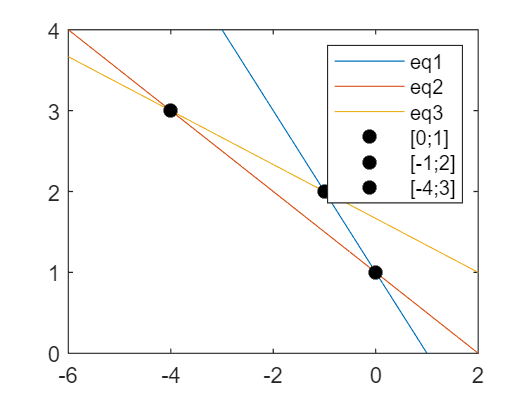

x1 = linspace(-6,2);
eq1 = 1-x1;
eq2=(2-x1)/2;
eq3=(5-x1)/3;
plot(x1,eq1,x1,eq2,x1,eq3), hold on
p1 = [0;1];
p2 = [-1;2];
p3 = [-4;3];
plot(p1(1),p1(2),'k*','Linewidth',2),plot(p2(1),p2(2),'k*','Linewidth',2),plot(p3(1),p3(2),'k*','Linewidth',2)
axis([-6,2,0,4])
legend('eq1','eq2','eq3','[0;1]','[-1;2]','[-4;3]')
hold off

#### **Equacions normals** 

Si el conjunt de solucions de **Ax=b** és buit, amb freqüència estem interessats en trobar $x=(x_1,x_2,\cdots,x_n)^t$ tal que el vector residu ${\bf r} =\| r(x)\|_2 =  \|b-Ax\|_2 $ sigui el més petit posible, valor mínim.

- Geomètricament, ${\bf Ax} = x_1\left( \begin{array}{l}a_{11}\\\vdots\\a_{m1}\end{array}\right)+\cdots+x_1\left( \begin{array}{l}a_{1n}\\\vdots\\a_{mn}\end{array}\right)$ es tracta de trobar la combinació lineal dels vectors columna de la matriu $\bf A$més propera al vector $\bf b$. La distància és $r(x) = b-Ax$, i el mínim es dona quan el vector $r(x)$ és perpendicular al subespai generat per els vectors columna de la matriu $\bf A$. Les equacions són ${\bf A^t\,r=A^t(b-Ax)=0}$. 

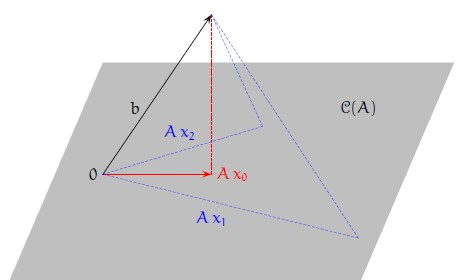

- Analíticament, si $x=(x_1,x_2,\cdots,x_n)^t$, $ {\bf r}^2\, =\displaystyle \sum_{i=1}^{m}(a_{i1}x_1+\cdots+a_{in}x_n-b_i)^2 = \displaystyle \sum_{i=1}^{m}\left( \sum_{j=1}^{n}a_{ij}x_j-b_i\right)^2$.  Els extrems locals han de verificar $\frac{\partial\, {\bf r^2}}{\partial x_j} =0$  per a tot $j=1,\dots,m$. Aquesta condició és  $2\displaystyle \sum_{i=1}^{m}\left( \sum_{k=1}^{n}a_{ik}x_k-b_i\right)^2 a_{ij} = 0$ ,  o $\displaystyle \sum_{i=1}^{m}\sum_{j=1}^{n}a_{ij}a_{ik}x_k = \sum_{i=1}^{m}a_{ij}b_i$ per a tot $j=1,\dots,m$. Escrit més compacte ${\bf A^tb=A^tAx}$.  

**Equacions normals**

A = [1 1; 1 2; 1 3]

A =      1     1
     1     2
     1     3


b=[1;2;5]

b =      1
     2
     5


AtA=A'*A

AtA =      3     6
     6    14


r = rank(AtA)

r =      2


d = det(AtA)

d =      6


x_m=linsolve(AtA,A'*b)

x_m =       -1.3333
            2



hold on  
plot(x_m(1),x_m(2),'g*','Linewidth',2)
legend('eq1','eq2','eq3','x1=[0;1]','x2=[-1;2]','x3=[-4;3]','x_m','Location','best')

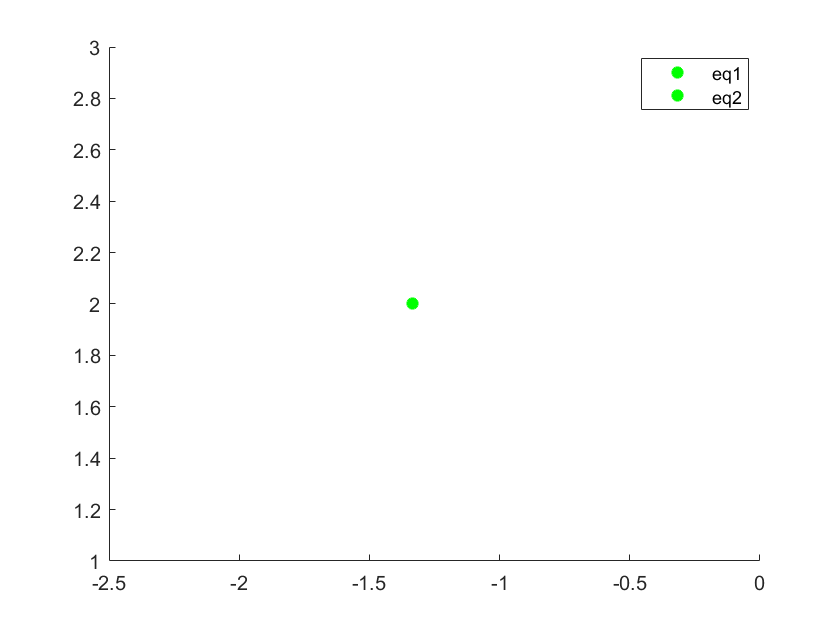

hold off

**El residu és mínim?**

r_x=norm(b-A*x_m)^2

r_x =       0.66667


r_y1=norm(b-A*[0;1])^2

r_y1 =      4


r_y2=norm(b-A*[-1;2])^2

r_y2 =      1


r_y3=norm(b-A*[-4;3])^2

r_y3 =      4


Proves per justificar residu mínim

% un joc de proves amb vectors qualsevols (randn)
r_x=norm(b-A*x_m)^2

r_x =       0.66667


format shortG
for k=1:5000
    y=randn(2,1);
    r_y(k)=norm(b-A*y)^2;
end
sum(r_x > r_y)

ans =      0


#### *Exercici 20 de la llista Problemes_2023.*

Determineu la solució d'error quadràtic mínim per al sistema linal següent:


$$S = \left\{ \begin{array}{rcrcrcrcr}
x & + & y & + & z &   &    & = & 2\\ 
x &   &   & + & z & + & 2t & = & 3\\ 
x & + & y &   &   & + & t  & = & 4\\
& - & y & + & 2z&   &    & = & 2\\ 
-x & + & y & - & z & + & t  & = & 1
\end{array}\right.$$
   

`Exercici 1`` Escriviu A i b i calculeu rang(A).`

% Per fer

`Exercici 2`` Calculeu `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comprova que el sistema `${A^tAx=A^tb}$` és compatible determinat. `

% Per fer

`Exercici 3`` Calculeu `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`.  `

% Per fer

`Exercici 4`` Calculeu el vector residu en la solució. Comproveu que `$y=(0,-1,2,-1)^t$`  té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

% Per fer

`Exercici 5``. `

`A continuació obteniu la solució del sistema S fent ús les comandes de MATLAB®: \, linsolve i lsqminnorm. Què observeu? `

% Per fer

#### *Exercici 21 de la llista Problemes_2023.*

Els pesos atòmics de l'oxigen i del nitrogen són aproximadament $O=16$ i $N=14$; utilitzeu els pesos moleculars dels sis òxids de nitrogen de la taula per tal d'ajustar els pesos atòmics per mínims quadrats

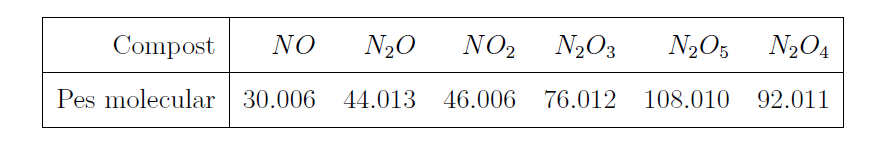

`Exercici 1`` Escriviu A i b i calculeu rang(A)`

% Per fer

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comprova que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

% Per fer

`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

% Per fer

`Exercici 4``  Calculeu el vector residu en la solució. Comproveu que `$O=16$` i `$N=14$` té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

% Per fer

#### *Exercici 22 de la llista Problemes_2023.*

Determineu  una funció quadràtica que satisfaci al màxim (error quadràtic mínim) la taula següent:

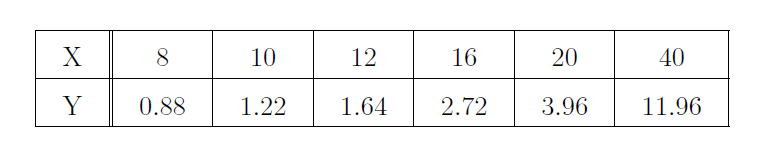

`Exercici 1`` Escriviu el sistema lineal associat al problema,  Ax=b, explícita A, b i rang(A).`

% Càlculs per fer

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

% Càlculs per fer

`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$ f`ent ús de la factorització LU de la matriu `$A^tA$`.  `

% Càlculs per fer

`Exercici 4`` Representeu les dades i la funció quadràtica obtinguda en un mateix gràfic.  `

% Càlculs per fer


`Document preparat per M. Àngela Grau Gotés, 1 de març de 2023`